fileID = fopen('014ICR_20230610.Logger.bin');
A = fread(fileID,'int16',2);
fseek(fileID,2,'bof')

ans = 0

B = fread(fileID,'int16',2);

T = 0:(length(A)-1);
T = T/100;
A = A/5;
B = B/5;

% spectrumの計算
movingwin       = [4 4];        % set the moving window dimensions
params.fpass    = 1:20;            % frequency of interest
params.tapers   = [2 3];            % tapers
params.pad      = 0;
params.trialave = 0;                % average over trials
params.err      = 0;                % no error computation
params.Fs = 100; % sampling frequency
[s1,tsp,fsp] = mtspecgramc(B, movingwin, params); % compute spectrogram


figure;
ax1 = subplot(3,1,1);
plot(T,B)
%title('EEG')
%xlim([0 T(length(T))])
%xlim([70000 100000])
%ylim([-500,500])
ax1.XTickLabel = []; 
ax1.YLabel.String = 'EEG';
ax2 = subplot(3,1,2);
%spectrogram(B,1024,800,1024,100)
pcolor(tsp,fsp,log10(s1')); shading interp;
colorbar off
%title('spectrogram')
%xlim([70000 100000])
%view(90,-90)
ax2.XTickLabel = []; 
ax2.YLabel.String = 'spectrogram';
ax3 = subplot(3,1,3)

ax3 =   Axes のプロパティ:

             XLim: [0 1]
             YLim: [0 1]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.2157]
            Units: 'normalized'

  すべてのプロパティ を表示


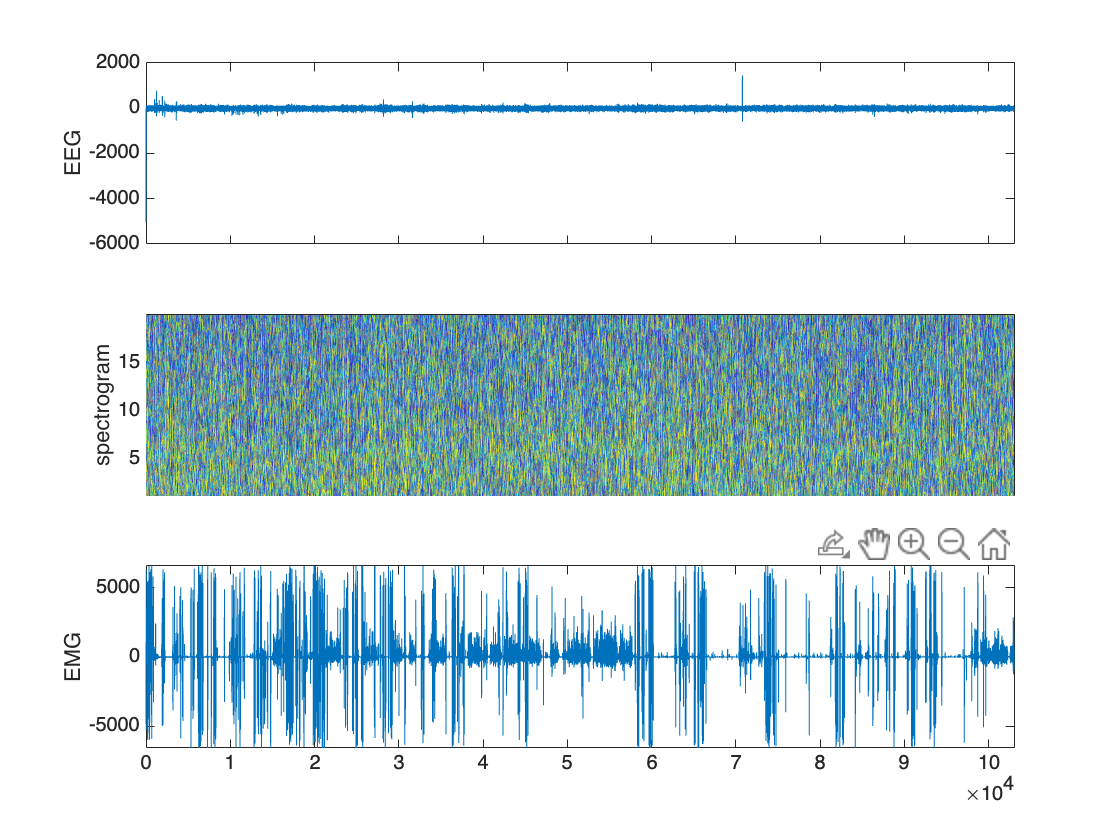

plot(T,A)
%title('EMG')
%xlim([70000 100000])
%ylim([-2000,2000])
ax3.YLabel.String = 'EMG';

linkaxes([ax1,ax2,ax3],'x')
axis tight